## **Soft Manipulator Actuation** 

We created a 0.9m soft beam with radius linearly varying from 3cm to 1cm. The link consists of 2 divisions, the first division is 0.4m long and the second is 0.5m long.

All modes of deformation are enabled with a quadratic Legendre Polynomial parameterization

SorosimLink (`L1`) and SorosimLinkage (S`1`) are saved in `SoftManipulator.mat`

load('SoftManipulator.mat')

To see the properties of `L1`

L1

L1 =   SorosimLink with properties:

    jointtype: 'N'
     linktype: 's'
         npie: 3
           ld: {[0.4000]  [0.5000]}
            L: [0.9000]
           CS: 'C'
            r: {@(X1)X1.*(-8.9e-3)+3.0./1.0e+2  @(X1)X1.*(-1.11e-2)+2.11e-2}
            h: {[]  []}
            w: {[]  []}
            a: {[]  []}
            b: {[]  []}
           cx: []
           gi: {[4×4 double]  [4×4 double]}
           gf: {[4×4 double]  [4×4 double]}
            E: [1000000]
          Poi: [0.5000]
            G: [3.3333e+05]
          Eta: [10000]
          Rho: [1000]
           Kj: []
           Dj: []
            M: []
          n_l: [25]
          n_r: [18]
        color: [0.6797 0.6551 0.1626]
        alpha: [1]
          CPF: [0]
       PlotFn: @(g)CustomShapePlot(g)
       Lscale: [0.1365]

To see the properties of S`1`

S1

S1 =   SorosimLinkage with properties:

                      N: 1
                   ndof: 36
                   nsig: 15
                     nj: 13
                 VLinks: [1×1 SorosimLink]
              LinkIndex: 1
                 CVRods: {[1×3 SorosimRod]}
                  iLpre: 0
                  g_ini: [4×4 double]
                Z_order: 4
               OneBasis: 0
                   nCLj: 0
                   iCLA: []
                   iCLB: []
               VRodsCLj: []
                  gACLj: []
                  gBCLj: []
           CLprecompute: [1×1 struct]
                   T_BS: []
                Gravity: 0
                      G: [6×1 double]
                     np: 0
            LocalWrench: [1×0 double]
                 Fp_loc: {0×1 cell}
                 Fp_vec: {0×1 cell}
                 Fp_sig: [0×1 double]
                    CEF: 0
             UnderWater: 0
              R

To see the problem definition:

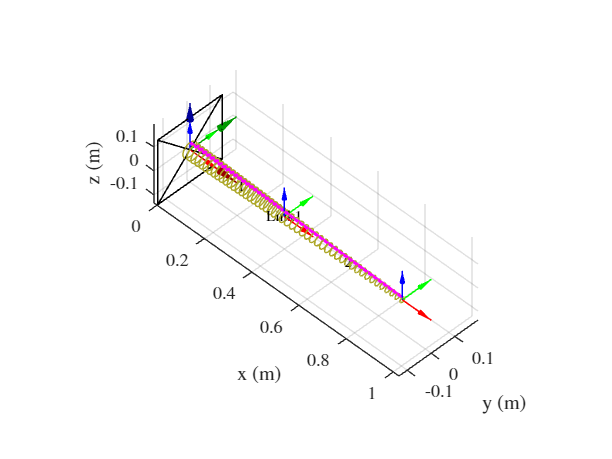

S1.plotq0

The result should be:

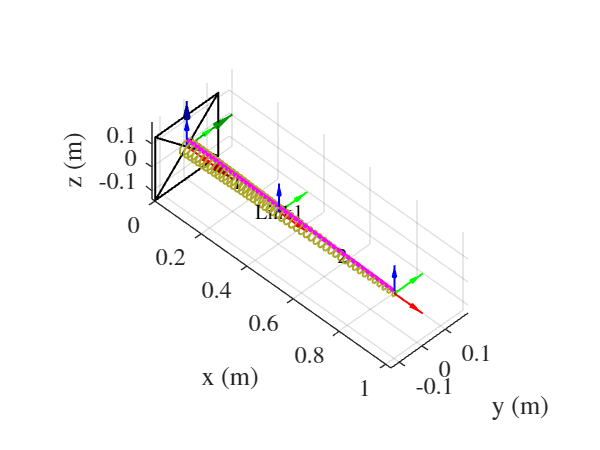

The beam is rigidly fixed at one end and can be subjected to actuation forces.

### **Static equilibirum analysis**

For statics equilibirum analysis type:

Solving Static Equilibrium

                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          1         1.25204e+14                        8.28e+15              1
     1          2         8.49911e+12              1         1.03e+15              1
     2          3             27202.5        2.36599         1.83e+10            2.5
     3          4         7.25725e-10    7.07481e-06          6.8e+03           5.91
     4          5         1.27554e-17     5.0566e-11             2.95           5.91
     5          6          4.0774e-18    8.86357e-16             1.51           5.91

Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the <a href 

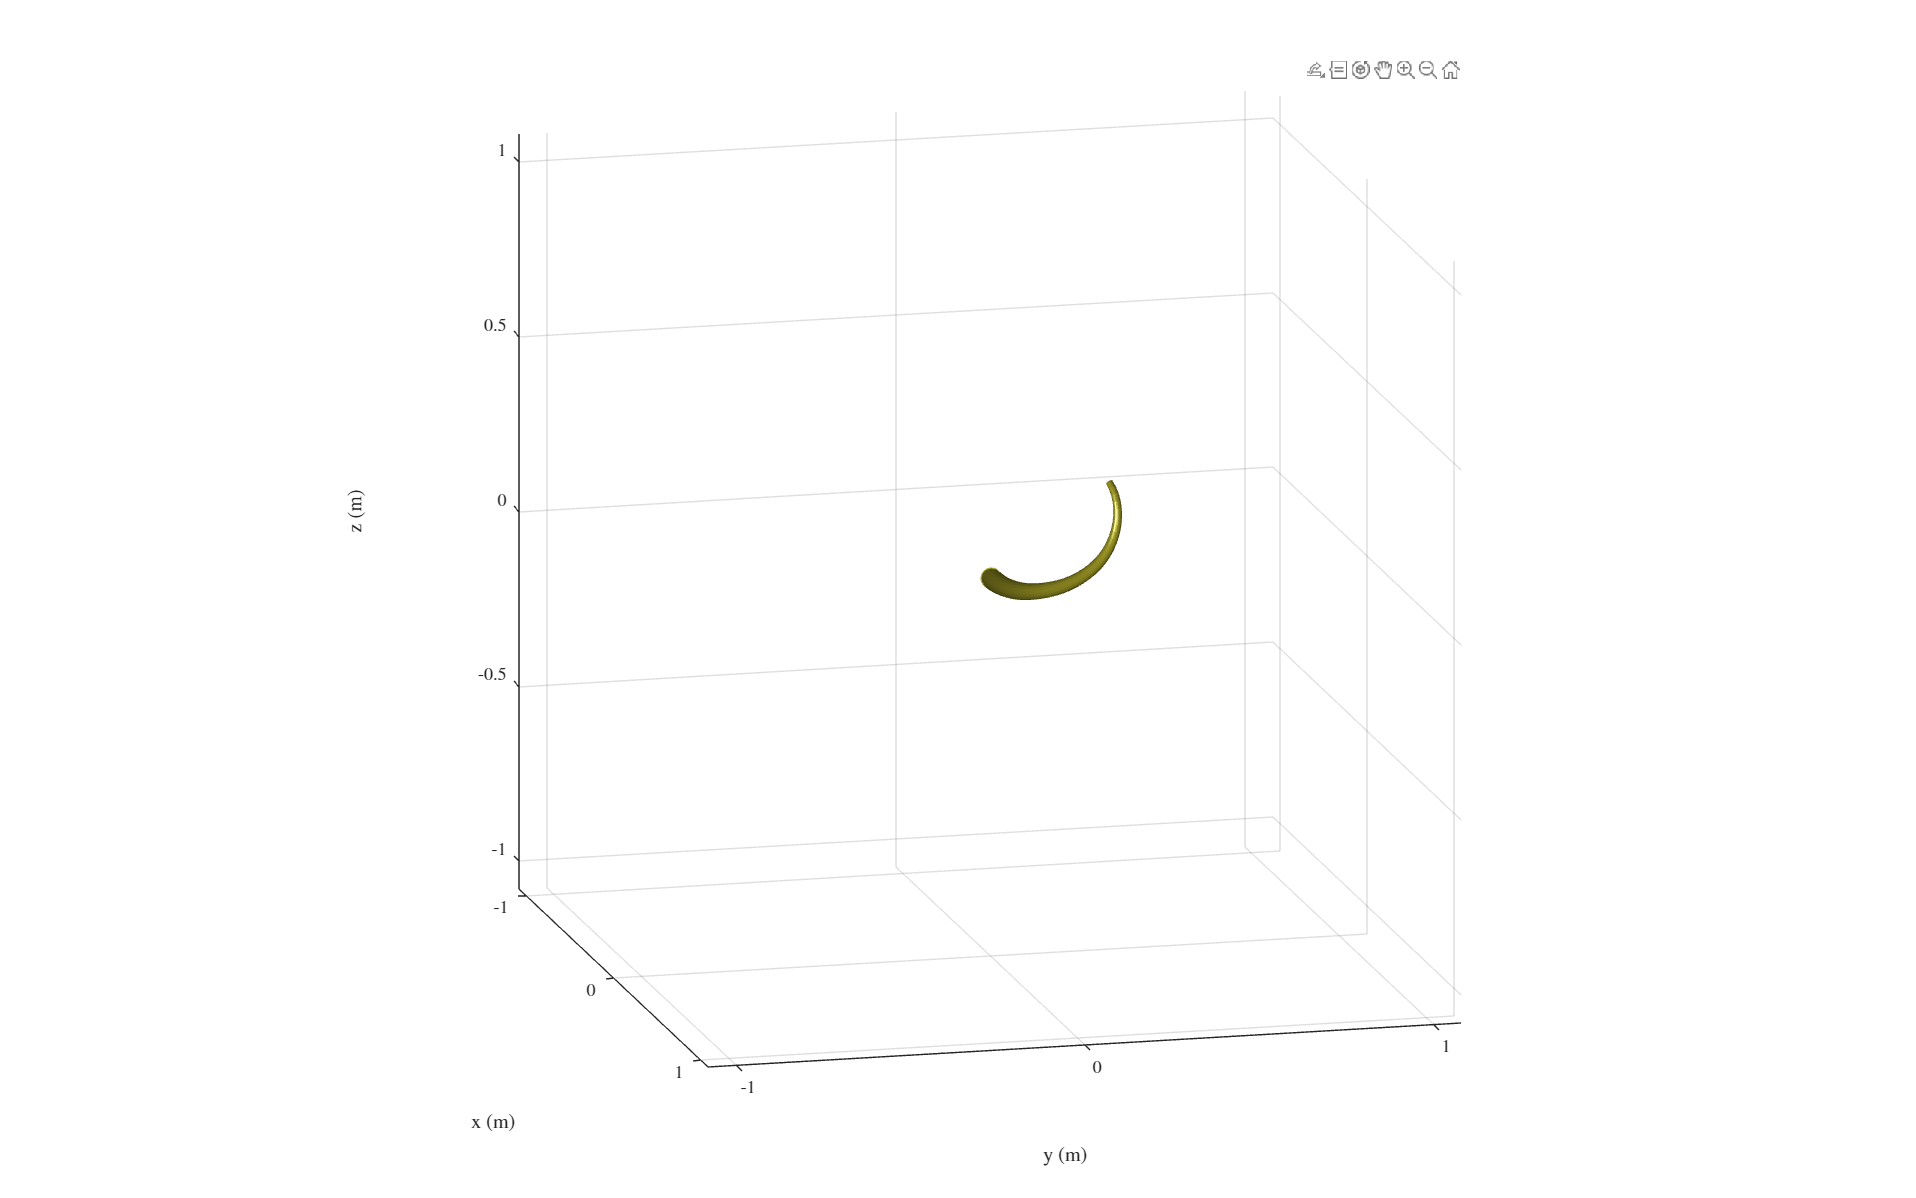

q=S1.statics;

You will be prompted to enter the actuation force in the command window. Enter the input actuation forces into cables 1 and 2 respectively. eg: -10, -15

A dialog box will then pop up, asking for the initial guess. The user can choose the default value.

The equilibirum solution is,

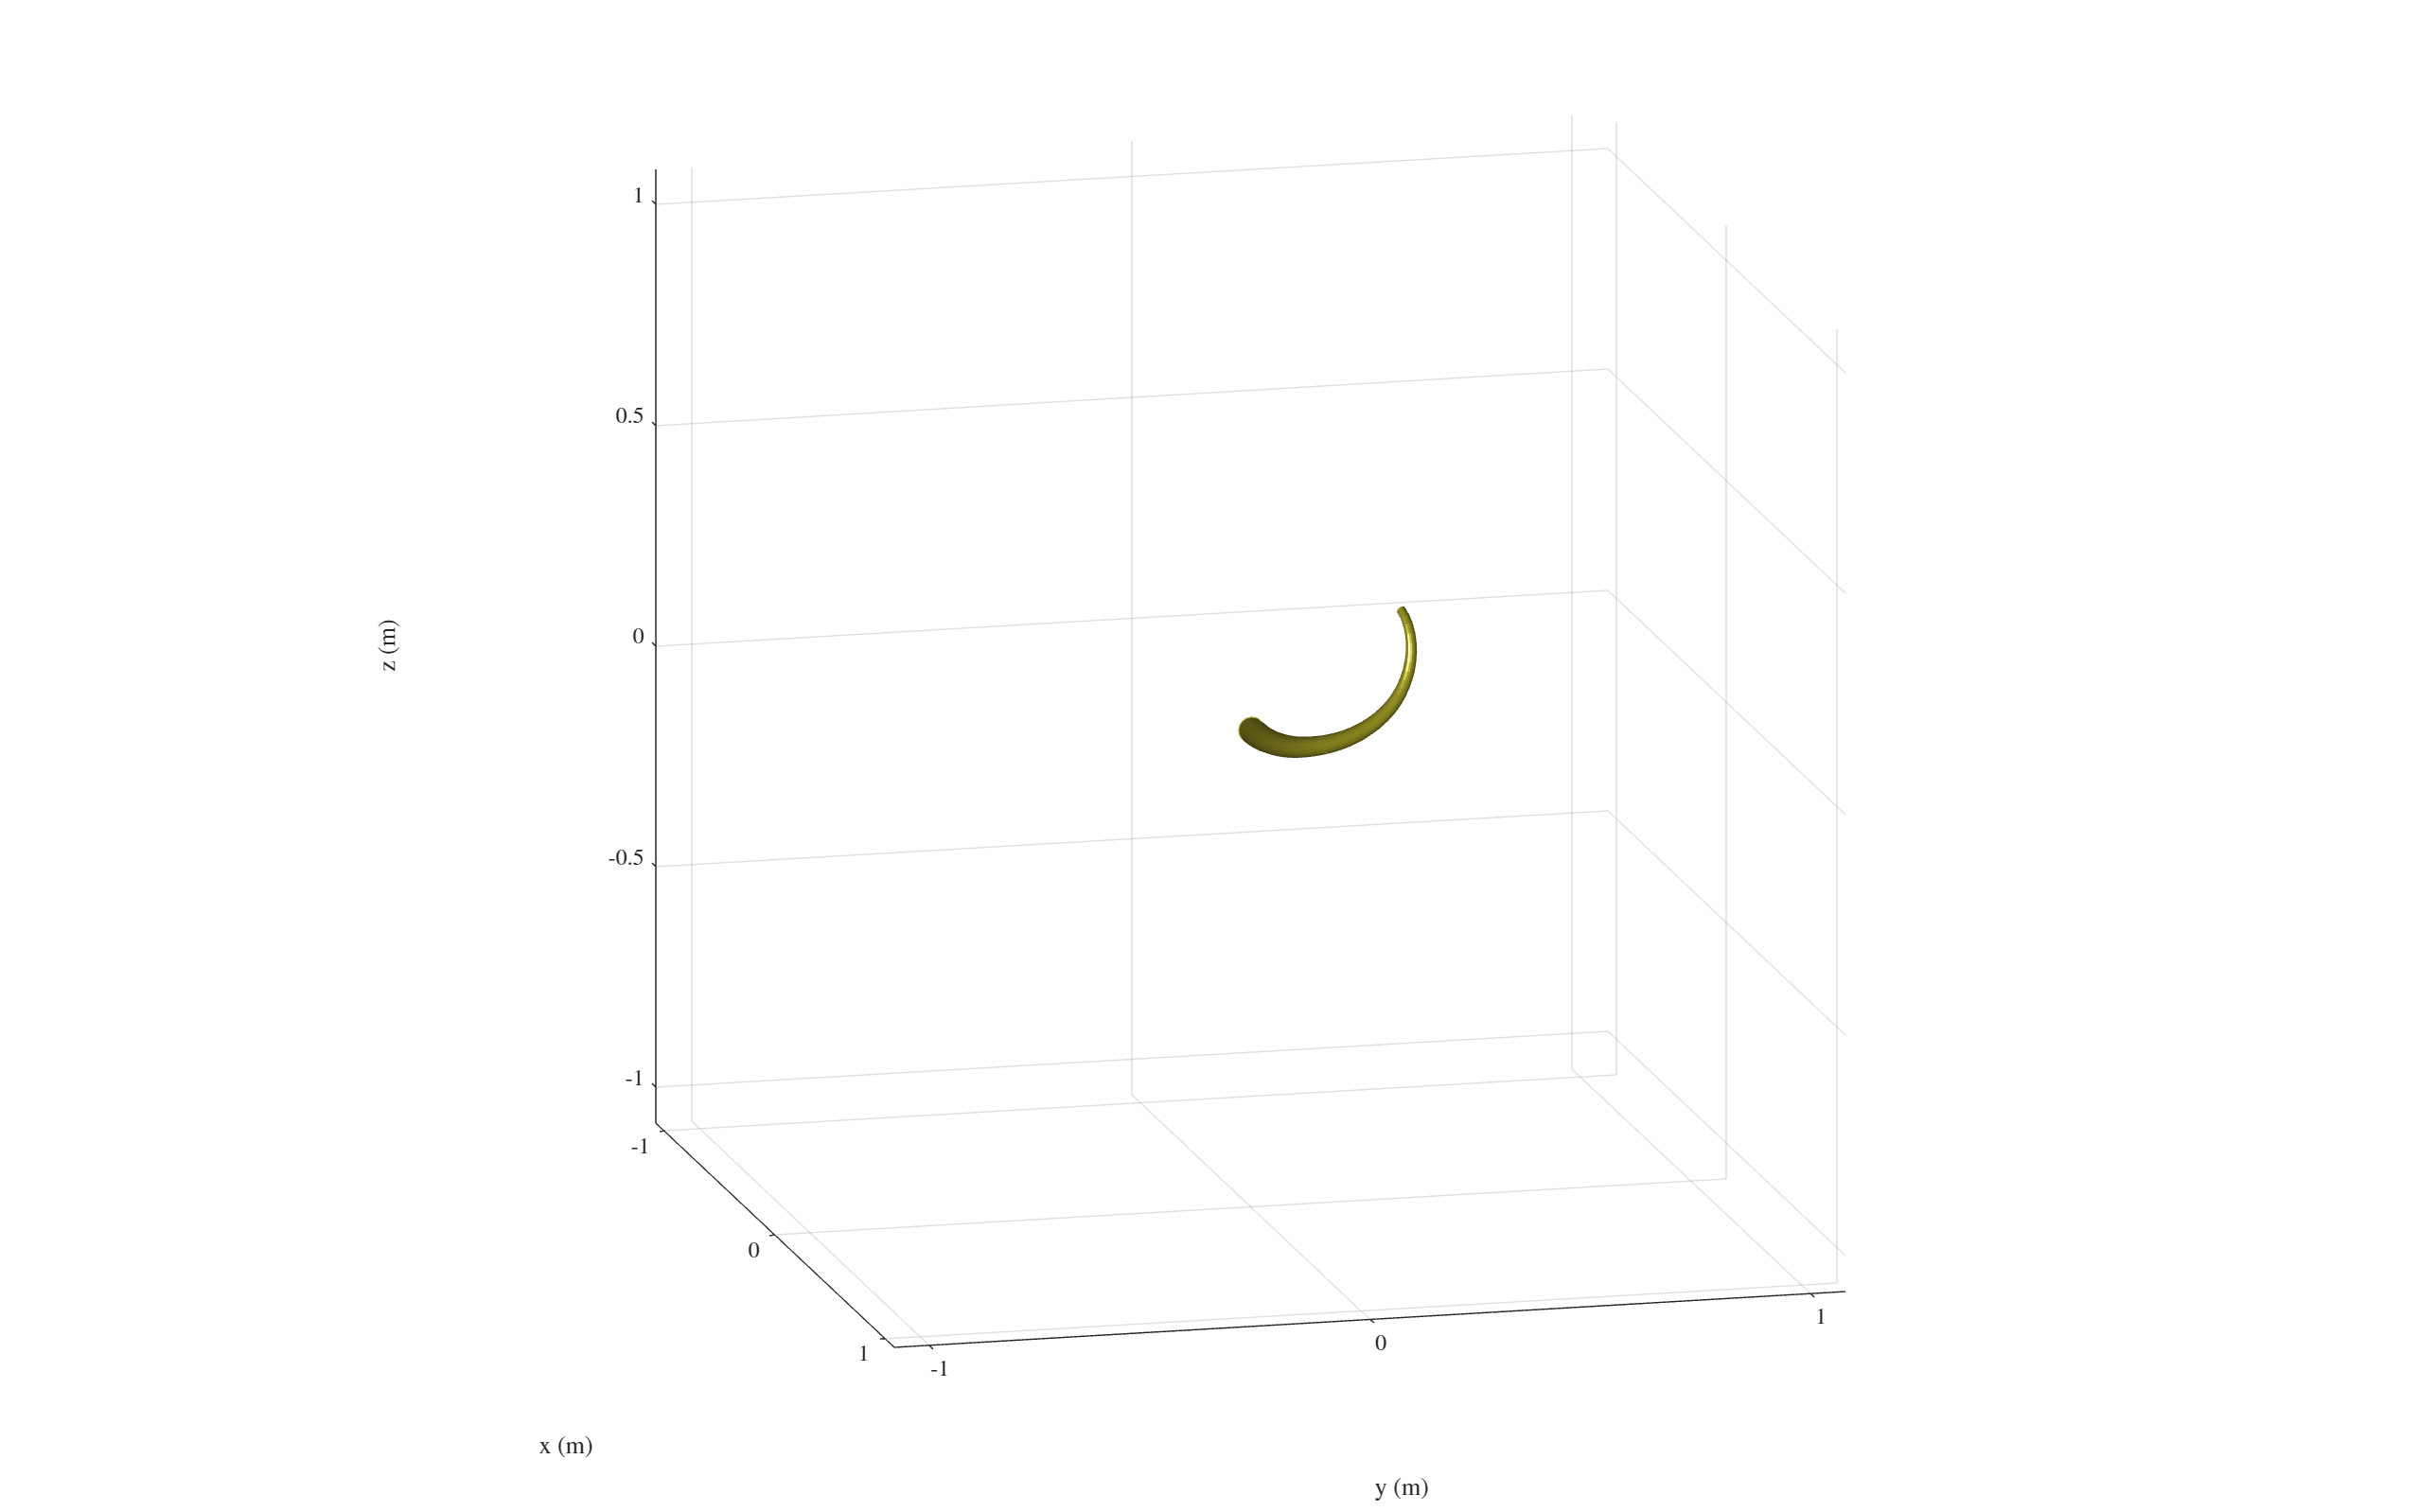

### **Dynamics**

For dynamics problem, type:

    0.6639
    1.6491
    3.5272
Elapsed time is 0.677684 seconds.


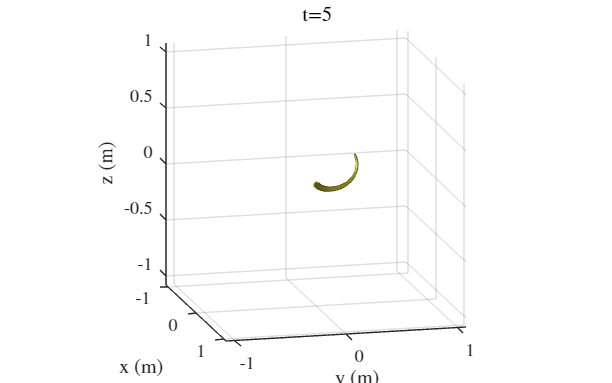

[t,qqd]=S1.dynamics;

The actuation input to the cables can be input by the user as a function of t in the command window.

Initial conditions of state coordinates ($$\mathbf{q_0}$$) and their derivatives ($$\mathbf{\dot{q_0}}$$) will then be asked in a dialog box. The user can also choose the time for which the simulation is run (the default value is 5 s).

The results of the dynamic simulation (`t` and `qqd`) will be saved in `DynamicsSolution.mat `in the folder from which the simulation is run.

At the end of simulation, in the dialog box that appear, choose to generate the video if needed.  This step will take some time. 

A video named `Dynamics.mp4` will be saved in the folder.

Enable gravity and try again.

S1.Gravity=true;